# Exercise 1: Estimation

#### LEDS Exam: September 11, 2023

Then, the identification problem should be solved following the steps below:

- **Understand the model structure**: The provided signals refer to either a ARX or an AR model. You should get the structure straight away from the measurements. Then display a coordinate graph where the x coordinate is the input signal and and the y coordinate is the output signal (something like plot(x,y,'o')), each coordinate couple (u(t),y(t)) should correspond to a point in the plot. The result is different if you do it for an AR o an ARX process.

- **Define the required estimation algorithm: **describe the algorithm you plan to use and why and add brief description of the matlab function you implemented accordingly. In this particular case you are asked to implement the batch version of the estimation algorithm.

- **Estimate the model order: **describe the criteria you plan to use and add brief description of the matlab function you implemented to do that.

- **Validate the model: **describe the criteria with hypothesis testing you plan to use to get model validation and add a description of the matlab functions you implemented to do that. 

clear all;
close all;
addpath ./Functions;

## 1] System measurements

N=5000;
Student = 'Simone Cenerini';
Matriculation = '0000983677';
[Measurements] = IdentifyThis(N, Student, Matriculation);
u=Measurements.u;
y=Measurements.y;

## 2] Data analysis & **Understand the model structure**:

We plot our obtained measurements:

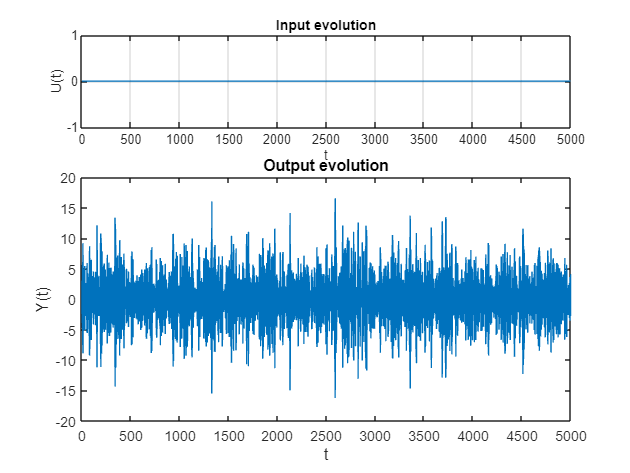

figure();
subplot(3,1,1);
plot(u);
grid on;
ylabel('U(t)');
xlabel('t');
title('Input evolution');

subplot(3,1,[2,3]);
plot(y);
xlim([0 N]);
ylabel('Y(t)');
xlabel('t');
title('Output evolution');

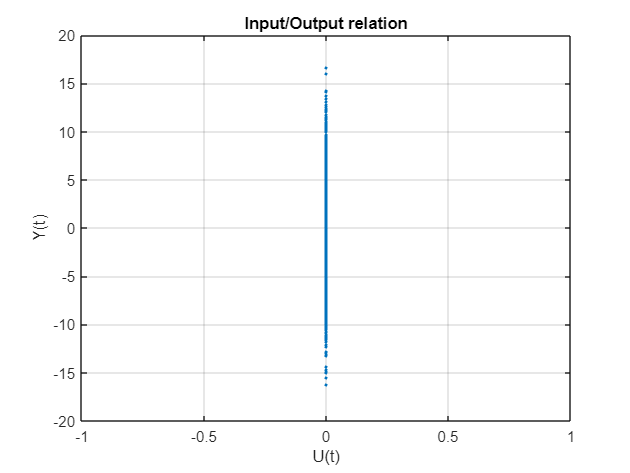

figure();
plot(u,y,'.');
grid on;
ylabel('Y(t)');
xlabel('U(t)');
title('Input/Output relation');

As we can see the input samples are identically equal to zero, this means that we don't have the input in our system and we can conclude that our system can be represented by a time series model, a model without the input, a *driving noise process*.

In particular we can conclude that we are dealing with an  **Auto-Regressive Time Series Model**.

The output is a typical stochastic output of a process.

The general equation of an **AR Model** of *order n* is the following:


$$y(t) + a_1 y(t-1) + \dots + a_ny(t-n)  = w(t)$$


where $w(t)$ is a *white process *with $0$ mean and variance $\sigma_w^2$.

We can write our problem according to the linear regression form:

 
$$y(t)=\varphi^T(t) \theta + e(t)
$$


where the regressor has the following expression ${\varphi \left(t\right)=\left\lbrack -y\left(t-1\right)\cdots -y\left(t-n\right)\right\rbrack }^T =\left\lbrack \;-\varphi_y^T \left(t\right)\;\right\rbrack$.

Our goal is to estimate the parameters vector ${\left.\theta =\lbrack a_1 \cdots a_n \right\rbrack }^T$.

We will put ourserlves in the persepective of an observer that is able only to measure the output of this AR process and does not know the value of $n$ (the model order) and the first of our problem is to retrieve it (chapter 4).

## **3] Define the required estimation algorithm:**

Since we have all the data available during the estimation, we were asked to use a batch version algorithm to estimate our parameters. In particular we are going to use a Least Square estimator, based on the minimization of the following loss function:


$$J\left(\theta \right)=\frac{1}{N}\sum_{t=1}^N {\left(y\left(t\right)-\varphi^T \left(t\right)\;\theta \right)}^2$$


Available in *"MyCostFunc.m"* 

By computing the derivatives of $J\left(\theta \right)$, in order to find a local minimum, is possible to observe that the loss function is quadratic. According to this quadratic nature of the loss function we can obtain a closed-form solution for the least square estimator:


$${\hat{\theta} }_{\mathrm{LS}} ={\left(\frac{H^T H}{N}\right)}^{-1} \left(\frac{H^T Y}{N}\right)$$


Available in *"MyLS.m"*

This formula requires the knowledge of the Hankel matrix $H$ and the obsterved outputs $Y$. Since we are dealing with an AR model we can say that $H$ has the following expression: 


$$H=\left\lbrack \begin{array}{cccc}
-y\left(0\right) & -y\left(-1\right) & \cdots  & -y\left(1-n\right)\\
\vdots  & \vdots  & \ddots  & \vdots \\
-y\left(N-1\right) & -y\left(N-2\right) & \cdots  & -y\left(N-n\right)
\end{array}\right\rbrack$$


Available in *"MyHankel.m"*

It's important to notice that if the disturbance was colored (for example an ARMAX process) instead of the white one, our cost function will not anymore be quadratic and so the optimal value for the parameter $\theta$ has to be computed in a recursive way, addressing the Prediction Error Method.

We can also highlight that there exist also a Recursive version of the Least Square algorithm that can be used in order to increase the performances in speed sense and case we are dealing with a real time system.

## **4] Estimate the model order:**

We are going to find the possible order $n$ from 0 to PP value. (Please note that in AR model $\left.n\equiv p\right)$

PP = 10;

### **4.1] Loss function analisys**

Evaluate the cost function until the order 10

J=zeros(PP,1);

for n=1:PP
    Hy = MyHankel(y,n);
    H=[-Hy];
    Theta_LS = MyLS(y,n,H);
    J(n) = MyCostFunc(y,H,Theta_LS,n);
end

Look at its plot

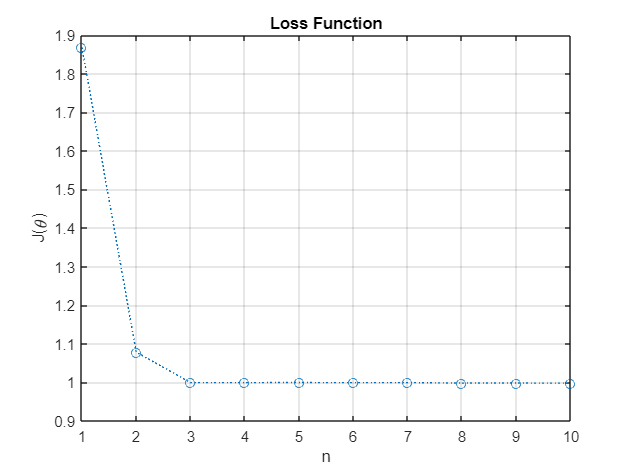

figure();
plot(J,':o');
grid on;
ylabel('J(\theta)');
xlabel('n');
title('Loss Function');

We can note that the loss function decreases faster until order 3 with respect to higher orders.

So, we can presume that the order of our system could be n=3.

### **4.2] Cost function estimation - **$J\left(\theta \right)$

The first method we try is to split the training set in two parts and so to obtain a *training set *and a *validation set.* Then:

- Find the estimate $\left({\hat{\theta} }_{\textrm{ls}} \right)$ by using only the first half of the data set (*training set)*

- Plot the cost function behaviour $\left(J\left({\hat{\theta} }_{\textrm{ls}} \;,Y_{\textrm{vl}} \right)\right)$by using the second half of the data set (*validation set)*

y_tr = y(1:N/2);
y_vl = y(N/2+1:end);

J_theta=zeros(PP,1);

for n=1:PP
    Hy = MyHankel(y_tr,n);
    H=[-Hy];
    Theta_LS = MyLS(y_tr,n,H);
    Hy = MyHankel(y_vl,n);
    H=[-Hy];
    J_theta(n) = MyCostFunc(y_vl,H,Theta_LS,n);
end

Now plot the result

[Theta_J,n_J]=min(J_theta); %Find minimun
fprintf('The minimun value is given with the order %d', n_J);

The minimun value is given with the order 6

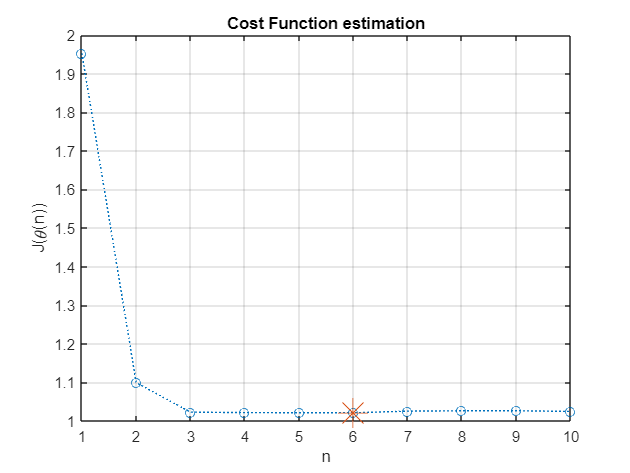

figure();
plot(J_theta,':o');
grid on;
hold on;
plot(n_J,J_theta(n_J),'*','MarkerSize',20); %Plot minimun
ylabel('J(\theta(n))');
xlabel('n');
title('Cost Function estimation');

We have obtained an estimation of the model complexity by looking at the minimum of the loss function but in the most of the cases this method overestimates the complexity.

### **4.3] CRITERIA WITH COMPLEXITY TERM - [FPE, AIC, MDL]**

Now we try to give a better solution of our *complexity selection problem* by means of the criteria with complexity terms.

These criteria are characterized by a term called 'Penalizing term' that increase the value of $J\left(\hat{\theta_N } \right)$ when the $p$ value (model complexity) increases. This avoids overfitting and fits well the parcimony principle.

**General form**


$$V\left(\hat{\theta_N } \right)=N\cdot \mathrm{logJ}\left(\hat{\theta_N } \right)+f\left(N,p\right)$$


**FPE (Final Prediction Error)**


$$FPE=J\left(\hat{\theta_N } \right)-\frac{2p}{N}J\left(\hat{\theta_N } \right)$$


**AIC (Akaike Information Criterion)**


$$AIC=N\cdot \mathrm{logJ}\left(\hat{\theta_N } \right)+2p$$


**MDL (Minimum Description Length)**


$$MDL=N\cdot \mathrm{logJ}\left(\hat{\theta_N } \right)+2p\cdot logN$$


All these methods are going to be implemented by using the training set, so we are going to reuse all the data that we have.

FPE = zeros(PP,1);
AIC = zeros(PP,1);
MDL = zeros(PP,1);

for n=1:PP
    H=-MyHankel(y,n);
    Theta_LS = MyLS(y,n,H);
    J_n = MyCostFunc(y,H,Theta_LS,n);

    FPE(n) = J_n * ((N+n)/(N-n));
    AIC(n) = N*log(J_n) + 2*n;
    MDL(n) = N*log(J_n) + 2*n*log(N);
end


Now we are going to plot the results obtained from each criteria

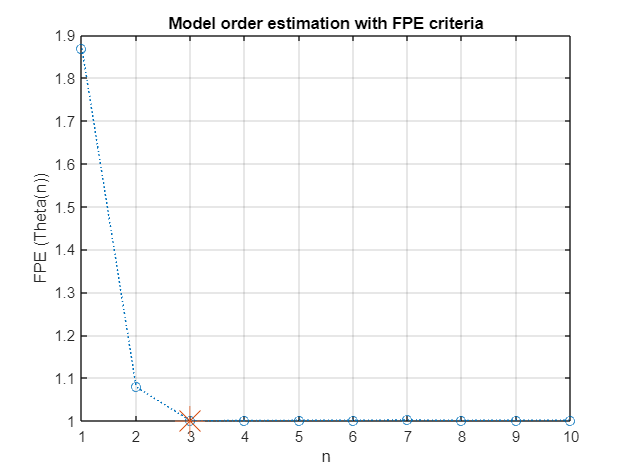

[~, n_FPE]=min(FPE);
Plot_complexity_term(FPE,n_FPE,'FPE');

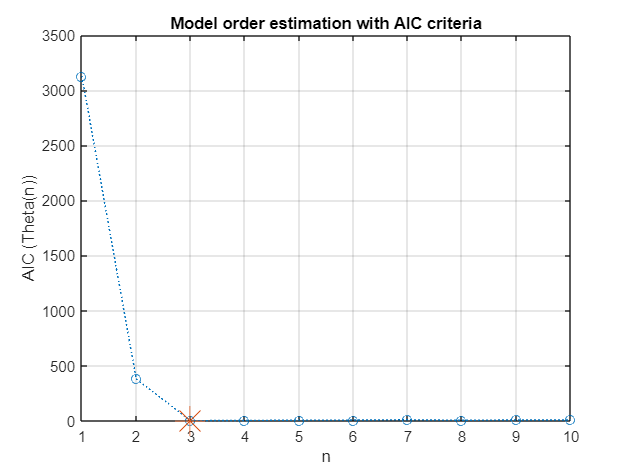

[~, n_AIC]=min(AIC);
Plot_complexity_term(AIC,n_AIC,'AIC');

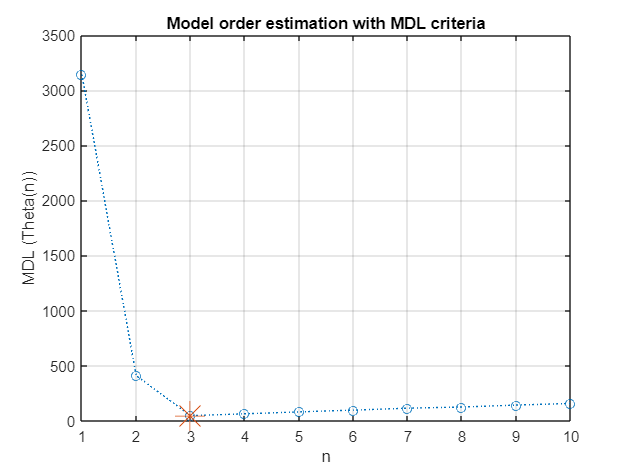

[~, n_MDL]=min(MDL);
Plot_complexity_term(MDL,n_MDL,'MDL');

### 4.4] Model order choice:

Now we are going to choose the model order by select the MDL result since is possible to prove it is a consistent method for order estimation.

fprintf('Order estimated from the different critiria:\n n_J \t n_FPE \t n_AIC \t n_MDL \n %d \t %d \t %d \t %d',n_J,n_FPE,n_AIC,n_MDL);

Order estimated from the different critiria:
 n_J 	 n_FPE 	 n_AIC 	 n_MDL 
 6 	 3 	 3 	 3

After having runned severals times “IdentifyThis.p”, if output samples are every time of the same system, I will declare that system is to order 3.

n_star = 3;

## **5] Parameter estimation:**

Once we have identified the order of the system, we are going to estimate the value of the parameter.

We are going to select different amount of samples to understend which is a reasonable value of samples.

N_samples = [10, 100, 1000, 5000, 10000, 100000, 1000000];
Theta_samples = zeros(length(N_samples),n_star);

for t= 1:length(N_samples)
    y = IdentifyThis(N_samples(t), Student, Matriculation).y;
    H=-MyHankel(y,n_star);
    Theta_samples(t,:) = MyLS(y,n_star,H);

    fprintf('For N = %d \nTheta_1: %.4f\tTheta_2: %.4f\tTheta_3: %.4f \n', N_samples(t),[Theta_samples(t,:)]);
end

For N = 10 
Theta_1: 1.8073	Theta_2: 1.5353	Theta_3: 0.7125 
For N = 100 
Theta_1: 1.7981	Theta_2: 1.2293	Theta_3: 0.3604 
For N = 1000 
Theta_1: 1.7215	Theta_2: 1.0499	Theta_3: 0.2549 
For N = 5000 
Theta_1: 1.7178	Theta_2: 1.0532	Theta_3: 0.2608 
For N = 10000 
Theta_1: 1.7176	Theta_2: 1.0346	Theta_3: 0.2485 
For N = 100000 
Theta_1: 1.7202	Theta_2: 1.0470	Theta_3: 0.2562 
For N = 1000000 
Theta_1: 1.7141	Theta_2: 1.0343	Theta_3: 0.2479 


Since increase the number of samples will increase the accuracy we are going to print the error with respect to the last N used before.

Theta_NORM_star = norm(Theta_samples(length(N_samples),:));
Theta_errors = zeros(length(N_samples),1);
for t= 1:length(N_samples)
    Theta_errors(t) = (norm(Theta_samples(t,:))-Theta_NORM_star)/Theta_NORM_star;
end

Plot it:

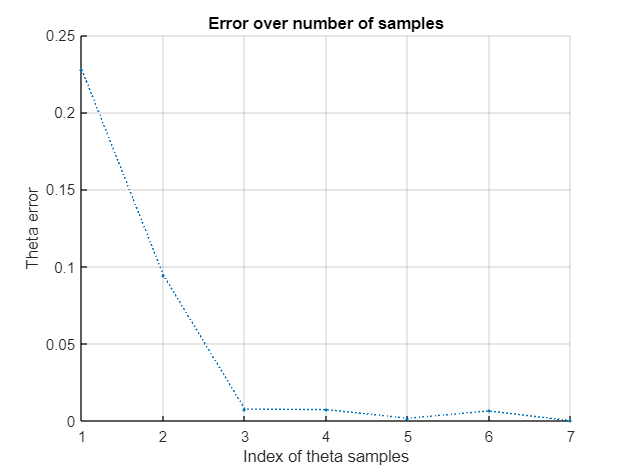

figure();
grid on;
hold on;
ylabel('Theta error');
xlabel('Index of theta samples');
title('Error over number of samples');
plot(Theta_errors,':.')

After having runned the* "IdentifyThis.p"* several times we can conclude that a reasonable value of samples is 5000. This value is a good trade-off between a good result and the parsimony principle.

Despite this, since we have already evaluated the estimator for the bigger possible amount of data, we have chose to use this solution and not to loose the accuracy.

Theta_star = Theta_samples(length(N_samples),:)';

## 6] **Validate the model:**

In general, for the model validation, two different tests on the residuals $\varepsilon \left(t\right)$ can be used:

- The whiteness test

- The cross-correlation test between $\varepsilon \left(t\right)$and $u\left(t\right)$

But we are dealing with an AR Model and so we can only do the whiteness test.

The **test of Cross-correlation** consists in checking if the input signal u(t) is uncorrelated with the residual ε(t). So, we want to check if the cross correlation between u(t) and ε(t) is close to 0. But in this case, we have no input, it is unapplicable.

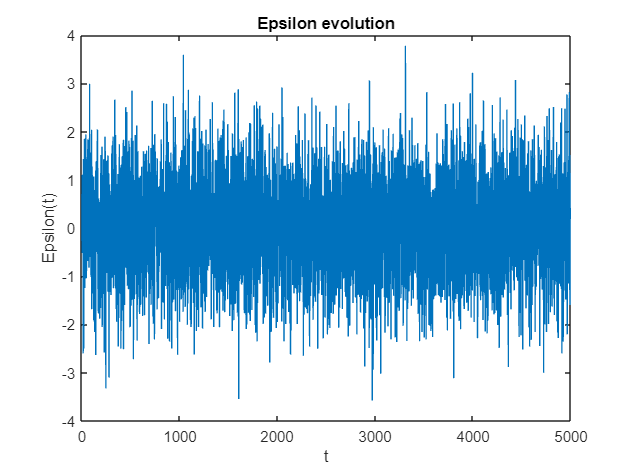

% y = IdentifyThis(N, Student, Matriculation).y;
% This is non truly correct since in this way we are going to use a
% validation set and this test can be performed on the training set.
y=y(1:N); % Because in the section above we downloaded more data.

H=-MyHankel(y,n_star);
N_star = N-n_star;
Y=y(1+n_star:end);
Y_hat = H*Theta_star;
Epsilon = Y - Y_hat;

figure();
plot(Epsilon)
ylabel('Epsilon(t)');
xlabel('t');
title('Epsilon evolution');

### 6.1] Whitness test

Considering the seqence of residual ε(t) obteined from the training set.

Consider the sample variance and the first $m$ terms of the auto correlation.

As a rule of thumb $m$ must be chosen in the interval $m\;\epsilon \left\lbrack 5,\frac{N}{4}\right\rbrack$.

The whiteness can be seen as the following Hypotesis test:


$$\left\lbrace \begin{array}{ll}
H_0  & \varepsilon \left(t,\hat{\theta_N } \right)\;\mathrm{is}\;\mathrm{zero}\;\mathrm{mean}\;\mathrm{white}\;\mathrm{process}\\
H_1  & \mathrm{not}\;H_0 
\end{array}\right.$$


The function written below implements the whiteness test by computing the first m samples autocorrelations (and the sample variance):


$$\hat{r_{\varepsilon } } =\left\lbrack \begin{array}{c}
\hat{r_{\varepsilon } } \left(1\right)\\
\hat{r_{\varepsilon } } \left(2\right)\\
\vdots \\
\hat{r_{\varepsilon } } \left(m\right)
\end{array}\right\rbrack$$


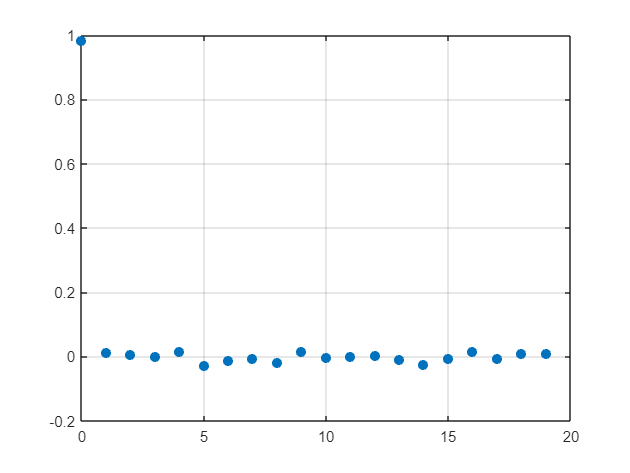

m = 20; %from [5,N/4]
r_epsilon = zeros(m,1);
for tau = 0:m-1
    r_idx = tau+1;
    for t = 1:(N_star-tau)
        if (t-tau) > 0
            r_epsilon(r_idx)=r_epsilon(r_idx) + Epsilon(t-tau)*Epsilon(t);
        end
    end
    r_epsilon(r_idx)=r_epsilon(r_idx)*(1/N_star);
end

figure();
plot(linspace(0, m-1,m),r_epsilon,'.','MarkerSize',20);
grid on;

Let make it easy, try the Matlab function

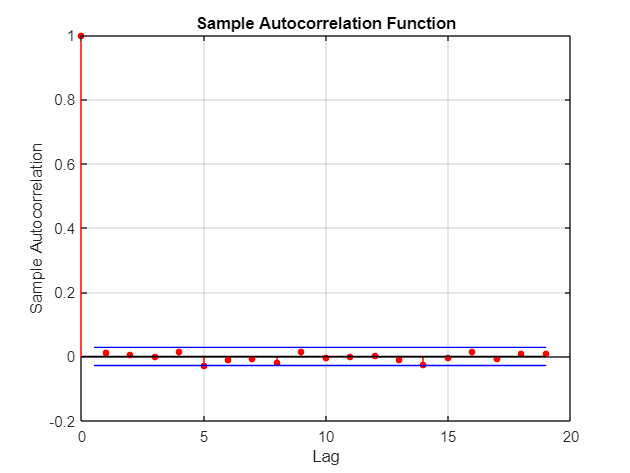

autocorr(Epsilon,m-1);

We obtein the same result, good!

Just by looking the graph is possible to confirm that is a white noise.

### 6.1.1] Chi-square test:

Now by evaluating the following test quantity:

$x=N\frac{\hat{{r_{\varepsilon } }^T } \hat{r_{\varepsilon } } }{\hat{{r_{\varepsilon } }^2 } \left(0\right)}\longrightarrow \chi^2 \left(m\right)\;$when $N\to \infty$

and check if it is Chi-Square distributed or not by implementing the following *Chi-Square distribution test*.


$$\left\lbrace \begin{array}{ll}
H_0 :x\le \chi_{\alpha }^2 \left(m\right) & \varepsilon \left(t,\hat{\theta_N } \right)\;\textrm{is}\;\textrm{zero}\;\textrm{mean}\;\textrm{white}\;\textrm{process}\\
H_1 :x>\chi_{\alpha }^2 \left(m\right) & \textrm{not}\;H_0 
\end{array}\right.$$


Alpha=0.05;
X=N*(r_epsilon(2:m)'*r_epsilon(2:m))/(r_epsilon(1)^2); %It's possible to proof that 'X' is Chi-Square distributed

if X<=chi2inv(1-Alpha,m) % H0 True
     fprintf('x = %.2f <= %.2f --> Epsilon is white --> The model is valid\n', X,chi2inv(1-Alpha,m)); 
      
else % H1 True
     fprintf('x = %.2f > %.2f --> Epsilon is not white --> The model is not valid\n', X,chi2inv(1-Alpha,m));
end

x = 16.16 <= 31.41 --> Epsilon is white --> The model is valid


### 6.1.2] Gaussianity test:

Another possible test consists on defining the normalized quantity:

$\hat{\gamma} \left(\tau \right)=\frac{\hat{r_{\varepsilon } } \left(\tau \right)}{\hat{r_{\varepsilon } } \left(0\right)}\;$with $\tau =1,2,\ldotp \ldotp \ldotp ,m$ 

Now by evaluating the new test quantity:

$x=\sqrt{N}\;\hat{\gamma} \left(\tau \right)\longrightarrow \mathcal{N}\left(0,1\right)\;$when $N\to \infty$

and check if it is Normal distributed or not by implementing the following Gaussianity* distribution test*.


$$\left\lbrace \begin{array}{ll}
H_0 :\left|x\right|\le \left(1-\frac{\alpha }{2}\right) & H_0^{\tau } \\
H_1 :\left|x\right|>\left(1-\frac{\alpha }{2}\right) & H_1^{\tau } 
\end{array}\right.$$


We need more samples than before, we need to perform this test for $\tau =1,2,\ldotp \ldotp \ldotp ,m$ after we had collected all this test we can perform the **Anderson test.**

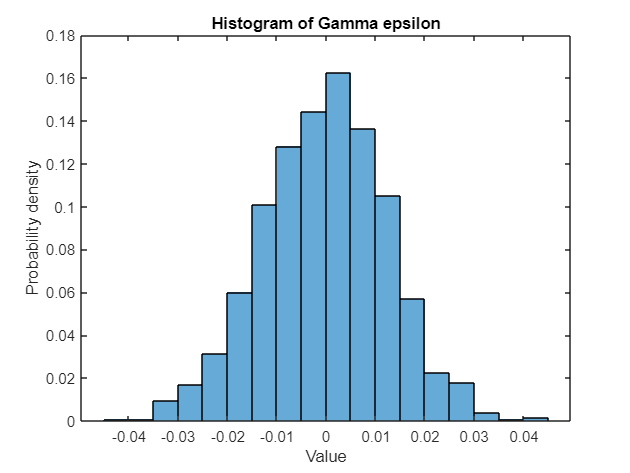

m =round(N_star/4); %from [5,N/4]
r_epsilon = zeros(m,1);
for tau = 0:m-1
    r_idx = tau+1;
    for t = 1:(N_star-tau)
        if (t-tau) > 0
            r_epsilon(r_idx)=r_epsilon(r_idx) + Epsilon(t-tau)*Epsilon(t);
        end
    end
    r_epsilon(r_idx)=r_epsilon(r_idx)*(1/N_star);
end

Gamma_epsilon = zeros(m-1,1);
for tau = 1:m-1
    r_idx = tau+1;
    Gamma_epsilon(tau) = r_epsilon(r_idx)/r_epsilon(1);
end

figure();
histogram(Gamma_epsilon, 'Normalization', 'probability','BinMethod','scott') % 'Normalization', 'pdf' normalizza l'istogramma
xlabel('Value');
ylabel('Probability density');
title('Histogram of Gamma epsilon');

It looks like a Normal distribution.

Gamma = 1-(Alpha/2);
mu = 0;
sigma = 1;
H1 = 0; %Number of failed test
for tau = 1:m-1
    X=sqrt(N)*Gamma_epsilon(tau); %It's possible to proof that 'X' is Gaussian distributed

    if X<=norminv(Gamma,mu,sigma) % H0 True
         %fprintf('x = %.2f <= %.2f --> Epsilon is white --> The model is valid\n', X,norminv(Gamma,mu,sigma)); 
          
    else % H1 True
         %fprintf('x = %.2f > %.2f --> Epsilon is NOT white --> The model is NOT valid\n', X,norminv(Gamma,mu,sigma));
         H1 = H1+1;
    end
end

To make the final decision we can use the *Anderson test, *where $\bar{m}$ (in the code $\left.H_1 \right)$ is the number of failed tests   


$$\left\lbrace \begin{array}{ll}
H_0 :\frac{\bar{m} }{m}\le \alpha  & \varepsilon \left(t,\hat{\theta_N } \right)\;\mathrm{is}\;\mathrm{zero}\;\mathrm{mean}\;\mathrm{white}\;\mathrm{process}\\
H_1 :\frac{\bar{m} }{m}>\alpha  & \mathrm{not}\;H_0 
\end{array}\right.$$


if (H1/(m-1))<=Alpha % H0 
    fprintf('%.3f <= %.2f --> Handerson test passed --> The model is valid\n', (H1/(m-1)),Alpha);
else % H1
    fprintf('%.3f > %.2f --> Handerson test NOT passed --> The model is NOT valid\n', (H1/(m-1)),Alpha);
end

0.011 <= 0.05 --> Handerson test passed --> The model is valid


0; % just a breakpoint

# Exercise 2: Classification

#### LEDS Exam: September 11, 2023

Then, the classification problem should be solved following the steps below:

- **Understand the feature set in space**: The provided training features are scattered in space in a particular (geometrical) way. Understand it and use it to define a "refined" feature set if needed. (Plotting them may result useful). Notice that the training set distribution in space changes at every run of the function, however the boundary shape is always the same. This can be handled easily in a well thought program.

- **Define the required classification algorithm: **describe the algorithm you plan to use and why and add brief description of the matlab function you implemented accordingly. 

- **Verify and test your classificator: **verify the obtained classificator on the provided training set and compute the related classification error. Then, try your classificator on the test set and plot your results together with the classification error on the test set.

clear all;
close all;
addpath ./Functions;

## 1] System measurements

N=5000;
Student = 'Simone Cenerini';
Matriculation = '0000983677';
[FeatureSet] = ClassifyThose(N,Student,Matriculation);
Utrain  = FeatureSet.Utrain;
Ytrain  = FeatureSet.Ytrain;
Utest   = FeatureSet.Utest;
Ytest   = FeatureSet.Ytest;

## 2] Data analysis:

First of all we plot the obtained data in order to understand the geometrical shape of the data.

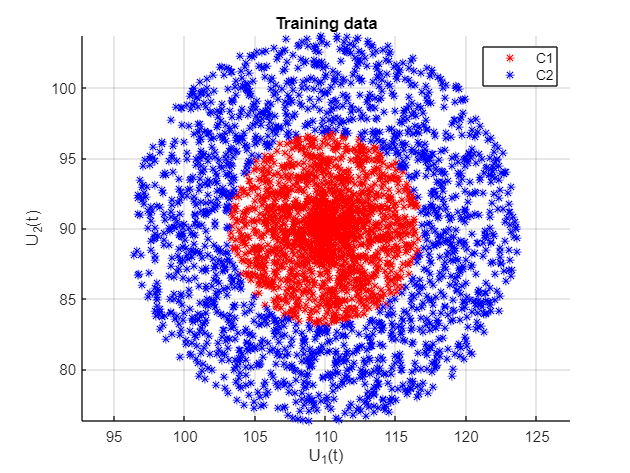

N_train = size(Utrain, 1);
dimension = size(Utrain, 2);
N_test = size(Utest, 1);

Plot_classification_data(Ytrain,Utrain,'U_1(t)','U_2(t)');

As we can easily see from the plot we are dealing with a *non linear problem* (the input space is non linear) and in particular the shape of the decision boundary is a circle.

### 2.1] N**on linear trasformation of the input space:**

The decision boundary is a circle with a centre of coordinates

 
$$\textrm{Centre}=\left(C_{U_1 } ;{C_U }_2 \right)$$


What we want to do is to linearize the input space and so redefine a new linear input space in order to have a linear decision boundary easier to be found.

With the following piece of code we try fo find the centre of the circular decision boundary by doing the aritmetic mean of the values of the input points.

Centre(1) = mean(Utrain(:,1));
Centre(2) = mean(Utrain(:,2));
fprintf('The centre is C = (%.2f,%.2f)\n', Centre(1), Centre(2));

The centre is C = (110.03,89.98)


Now we can introduce our non linear trasformation of the input space in order to obtain a linear boundary.


$$u\left(t\right)\;\epsilon \;U\longrightarrow v\left(t\right)=g\left(u\left(t\right)\right)\;\epsilon \;V$$


with $g\left(\cdot \right)$ non linear transformation.


$$u\left(t\right)=\left\lbrack \begin{array}{c}
u_1 \left(t\right)\\
u_2 \left(t\right)
\end{array}\right\rbrack \longrightarrow v\left(t\right)=\left\lbrack \begin{array}{c}
{\left(u_1 -C_{U_1 } \right)}^2 \\
{\left(u_2 -C_{U_2 } \right)}^2 
\end{array}\right\rbrack$$


in our particular case both the "original" and the linearized input spaces have the same dimension. Usually the dimension increase.

Firstly we centrilize the training set:

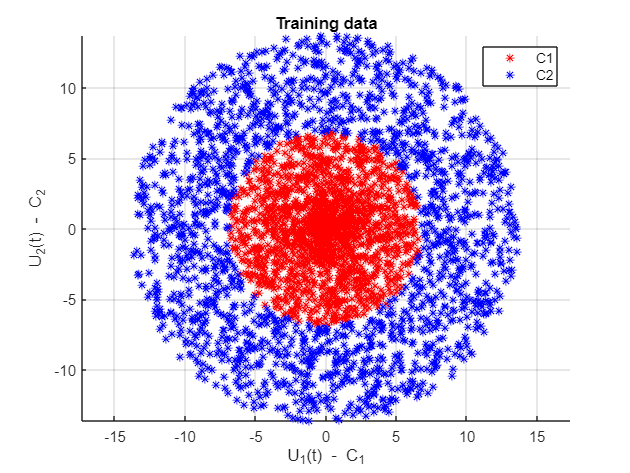

U_centered_train(:,1) = Utrain(:,1)-Centre(1);
U_centered_train(:,2) = Utrain(:,2)-Centre(2);

Plot_classification_data(Ytrain,U_centered_train,'U_1(t) - C_1','U_2(t) - C_2');

Since during the project we encountered an issue with the cost function ( which will be explained later on), one attempt was also made by normalizing the input samples to observe potential benefits on the sigmoid function and Hessian of the loss function.

However in conclusion of the project, a better result on error rate is achieved without samples normalization, but we need to be carefull with the choise of the initial condition and the stepsize.

To use normalized data change the value of *Normalize_Data* to *{ true, false}.*

Normalize_Data = false;

if Normalize_Data == false
    U_scalated_train(:,1) = U_centered_train(:,1);
    U_scalated_train(:,2) = U_centered_train(:,2);
elseif Normalize_Data == true
    U_scalated_train(:,1) = U_centered_train(:,1)/(max(U_centered_train(:,1)));
    U_scalated_train(:,2) = U_centered_train(:,2)/(max(U_centered_train(:,2)));
    Plot_classification_data(Ytrain,U_scalated_train,'U_1_s(t)','U_2_s(t)');
end

In conclusion we effectivly introduce the non linear transformation:

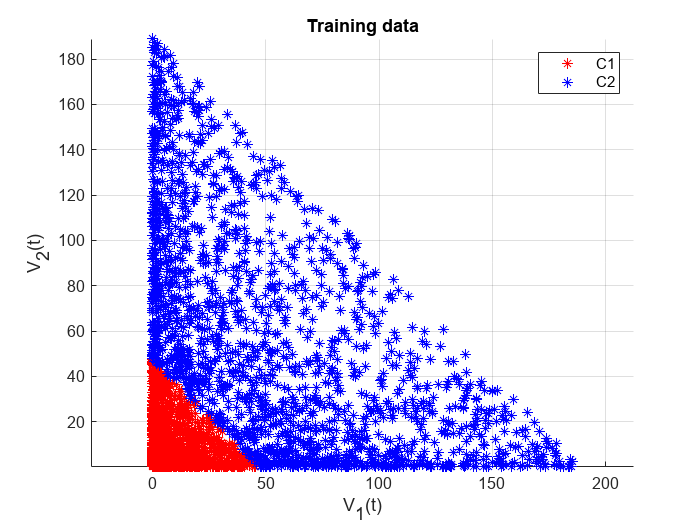

Vtrain(:,1) = U_scalated_train(:,1).*U_scalated_train(:,1);
Vtrain(:,2) = U_scalated_train(:,2).*U_scalated_train(:,2);

Plot_classification_data(Ytrain,Vtrain,'V_1(t)','V_2(t)');

## **3] Define the required classification algorithm:**

Now, thanks to our transformation, we are dealing with a linear classfication problem, and we are asked to solve this problem by means of **logistic regression**.

So our objective are the posterior probabilities $P\left(C_1 |u\left(t\right)\right)$ and $P\left(C_2 |u\left(t\right)\right)=1-P\left(C_1 |u\left(t\right)\right)$.

These probabilities are found using the following logistic sigmoid function 

$f\left(z\right)=\frac{e^z }{1+e^z }$, 

where $z\left(t\right)=\varphi^T \left(t\right)\theta \;$with $\varphi \left(t\right)={\left\lbrack 1\;\;v_1 \left(t\right)\;\;v_2 \left(t\right)\right\rbrack }^T$ and $\theta ={\left\lbrack \beta_0 \;{\;\;\beta }_1 \;\;\beta_2 \right\rbrack }^T$

In fact our decision boundary has the following form: $\beta_0 +\beta_1 \;\;v_1 \left(t\right)+\beta_2 \;\;v_2 \left(t\right)=0$.

Our estimate of the parameters $\hat{\theta}$ can be found by maximizing the following maximum likelihood function


$$P\left(Y|\theta \right)=\prod_{t=1}^N {P\left(C_1 |v\left(t\right)\right)}^{y\left(t\right)} \;{\left(1-P\left(C_1 |v\left(t\right)\right)\right)}^{1-y\left(t\right)} =\prod_{t=1}^N {f\left(z\left(t\right)\right)}^{y\left(t\right)} \;{f\left(z\left(t\right)\right)}^{1-y\left(t\right)}$$


that can be written in logaritmic form as


$$\log \;P\left(Y|\theta \right)=\sum_{t=1}^N \left\lbrack y\left(t\right)\;\log \;f\left(z\left(t\right)\right)+\left(1-y\left(t\right)\right)\;\log \;\left(1-f\left(z\left(t\right)\right)\right)\right\rbrack$$


Maximize the above function is equivalent to minimize its negative, so we have to find the estimate $\hat{\theta}$ minimizing $J\left(\theta \right)=-\log \;P\left(Y|\theta \right)$

The algorithm we use to find our estimate $\hat{\theta}$ is the recursive **Newton-Raphson algorithm**:


$${\hat{\theta} }^{k+1} ={\hat{\theta} }^k -\eta^k {{J^{\prime } }^{\prime } \left({\hat{\theta} }^k \right)}^{-1} {J^{\prime } \left({\hat{\theta} }^k \right)}^T$$


where $J^{\prime } \left(\theta \right)=\sum_{t=1}^N \left\lbrack f\left(z\left(t\right)\right)-y\left(t\right)\right\rbrack \;\varphi \left(t\right)=\;\Phi^T \left(F\left(\theta \right)-Y\right)$ 

and ${J^{\prime } }^{\prime } \left(\theta \right)=\sum_{t=1}^N f\left(z\left(t\right)\right)\left(1-f\left(z\left(t\right)\right)\right)\;\varphi \left(t\right)\;\varphi^T \left(t\right)=\;$$\Phi^T W\left(\theta \right)\Phi$

where $W\left(\theta \right)=\left\lbrack \begin{array}{cccc}
f\left(z\left(1\right)\right)\left(1-f\left(z\left(1\right)\right)\right) & 0 & \cdots  & 0\\
0 & f\left(z\left(2\right)\right)\left(1-f\left(z\left(2\right)\right)\right) & \cdots  & \vdots \\
\vdots  & 0 & \ddots  & 0\\
0 & \cdots  & 0 & f\left(z\left(N\right)\right)\left(1-f\left(z\left(N\right)\right)\right)
\end{array}\right\rbrack$

The stopping criterion fo the algorithm is the following

$\left(\frac{\left\|{\hat{\theta} }^{k+1} -{\hat{\theta} }^k \right\|}{\left\|{\hat{\theta} }^k \right\|}<\delta \right)$ || $\left(k>\bar{k} \right)$ 

We implemented the Newton-Raphson method starting with an initial Theta represented by a zero vector. The step size was chosen to decrease gradually in order to achieve faster results.

As mentioned earlier, during the project, we encountered an issue with the cost function. After improving the accuracy of Theta, the cost function resulted in 'Not a Number' (NaN). This occurred due to the logarithmic function when $f\left(z\right)$ give an informatical 1 or 0.

We manage this problem by introduce $\varepsilon \approx 0\;$inseide the logaritmic funcion, to ensure it never resulted in NaN.

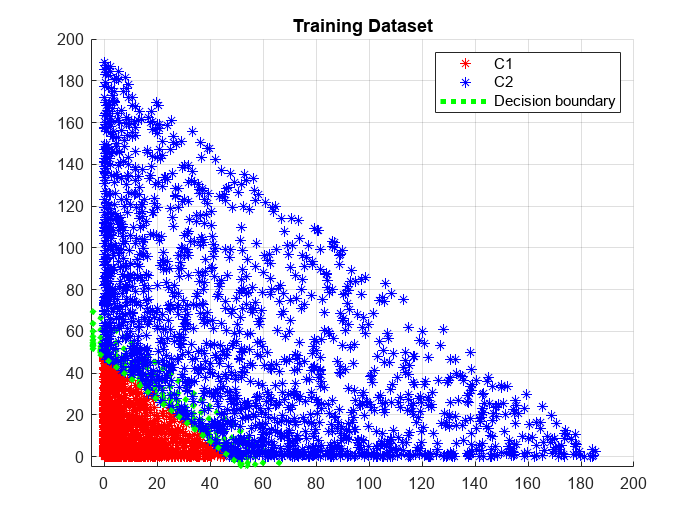

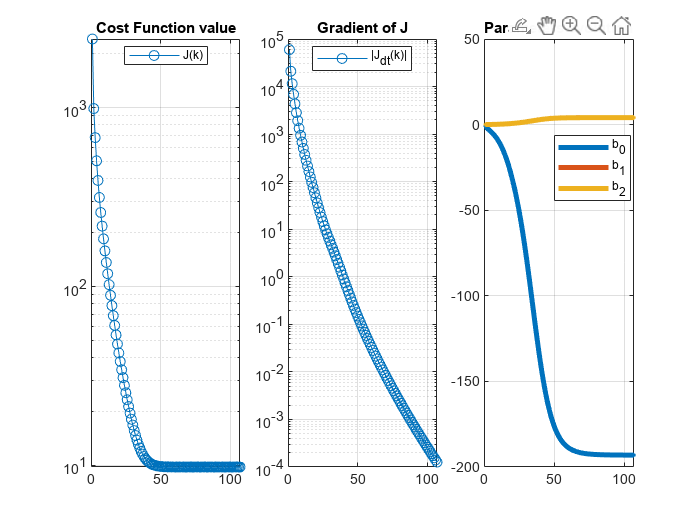

k=1	Stpz= 1.000	J= 2419.02	|J_dt|= 59840.4097	|J_ddt|= 3261097.21	|D|= 1.88	UpdateTheta= Inf 
k=2	Stpz= 0.707	J= 988.06	|J_dt|= 20960.3222	|J_ddt|= 1355053.36	|D|= 1.13	UpdateTheta= 0.426731 
k=3	Stpz= 0.577	J= 680.05	|J_dt|= 11482.5093	|J_ddt|= 717936.76	|D|= 1.29	UpdateTheta= 0.279000 
k=4	Stpz= 0.500	J= 504.42	|J_dt|= 6870.3747	|J_ddt|= 449895.83	|D|= 1.54	UpdateTheta= 0.224638 
k=5	Stpz= 0.447	J= 391.65	|J_dt|= 4328.4168	|J_ddt|= 315524.96	|D|= 1.83	UpdateTheta= 0.195240 
k=6	Stpz= 0.408	J= 314.70	|J_dt|= 2834.2546	|J_ddt|= 238607.33	|D|= 2.18	UpdateTheta= 0.177418 
k=7	Stpz= 0.378	J= 259.34	|J_dt|= 1915.3079	|J_ddt|= 189724.01	|D|= 2.59	UpdateTheta= 0.166218 
k=8	Stpz= 0.354	J= 217.55	|J_dt|= 1329.0949	|J_ddt|= 155925.04	|D|= 3.09	UpdateTheta= 0.158936 
k=9	Stpz= 0.333	J= 184.73	|J_dt|= 943.2946	|J_ddt|= 130953.93	|D|= 3.68	UpdateTheta= 0.153773 
k=10	Stpz= 0.316	J= 158.16	|J_dt|= 682.3523	|J_ddt|= 111578.05	|D|= 4.35	UpdateTheta= 0.149504 
k=11	Stpz= 0.302	J= 136.23	|J_dt|= 501.5

% Parameter & Costant
Plotting = true;
MAX_ITER = 200; % k bar
Theta_0 = [0;0;0];
Stopping_value = 0.00001;

% Algorithm
Phi = [ones(N_train,1) Vtrain(:,1) Vtrain(:,2)];
Y(find(Ytrain==2),1) = 1;
Y(find(Ytrain==1),1) = 0;
Theta = zeros(MAX_ITER,dimension+1);
Theta(1,:) = Theta_0;
J = zeros(MAX_ITER,1);
J_dt = zeros(MAX_ITER,dimension+1);

Plot_class = figure();
Plot_CostFun = figure();
Stopping_algorithm = false;
for k = 1:MAX_ITER
    stepsize = (1/(k^0.5)); %(1/k^a) with a = [0.5,1[
    %stepsize = 0.1;
    
    J(k) = LRCostFunc(Y,Phi,Theta(k,:)');
    J_dt(k,:) = LRCostFuncGrad(Y,Phi,Theta(k,:)');
    J_ddt = LRCostFuncHessian(Y,Phi,Theta(k,:)');
    Descent = (inv(J_ddt)*(J_dt(k,:)'))';

    Theta(k+1,:) = Theta(k,:) - stepsize*Descent; 
    
    Stopping_criteria = norm(Theta(k+1)-Theta(k))/norm(Theta(k));
    
    Norm_J_dt(k) = norm(J_dt(k,:));
    fprintf('k=%d\tStpz= %0.3f\tJ= %.2f\t|J_dt|= %.4f\t|J_ddt|= %.2f\t|D|= %.2f\tUpdateTheta= %.6f \n' ...
        ,k,stepsize,J(k),Norm_J_dt(k),norm(J_ddt),norm(Descent),Stopping_criteria);
    
    if Stopping_criteria < Stopping_value
        Stopping_algorithm = true;
    end

    if (Plotting == true) && (mod(k,10)==0 || k<10 || Stopping_algorithm == true)
        %subplot(2,3,[1 3]);
        figure(Plot_class);
        hold on 
        grid on 
        plot(Vtrain(find(Ytrain==1),1),Vtrain(find(Ytrain==1),2),'r*'); %C1
        plot(Vtrain(find(Ytrain==2),1),Vtrain(find(Ytrain==2),2),'b*'); %C2
        Xlim=xlim();
        xspace = Xlim(1):0.1:Xlim(end);
        BoundaryLine = (Theta(k,1) + xspace.*Theta(k,2))./(-Theta(k,3));
        plot(xspace,BoundaryLine,':g','LineWidth',3);
        Ylim=ylim();
        Ylim(1)=-5;
        ylim(Ylim);
        Xlim(1)=-5;
        xlim(Xlim);
        if Normalize_Data == true
            xlim([-0.1,1.1]);
            ylim([-0.1,1.1]);
        end
        hold off
        title('Training Dataset');
        legend({'C1','C2','Decision boundary'});
        
        figure(Plot_CostFun);
        subplot(1,3,1);
        semilogy(1:k,J(1:k),'o-');
        grid on;
        title('Cost Function value');
        legend({'J(k)'},'Location', 'Best');      

        subplot(1,3,2);
        semilogy(1:k,Norm_J_dt(1:k),'o-');
        grid on;
        title('Gradient of J');
        legend({'|J_d_t(k)|'},'Location', 'Best');      

        subplot(1,3,3);
        plot(1:k,Theta(1:k,:),'.-','LineWidth',3);
        grid on;
        title('Parameters evolution');
        legend({'b_0','b_1','b_2'},'Location', 'Best');      
        
        pause(0.01);
    end

    if Stopping_algorithm == true;
        break
    end
end

We obtained a great result !!

The cost function reaches its minimum around 10. The gradient of the cost function approaches zero, indicating that we have perfectly achieved the minimum, and it decreases in a quadratic manner. Additionally, the descent direction almost reaches zero, indicating that we are precisely at the minimum.

To make the optimal Theta values more understandable, we need to scale them by dividing them by their maximum value.

Theta_star = Theta(k+1,:)';
Theta_star = Theta_star/max(Theta_star);
fprintf('The estimated parameters are [%.2f %.2f %.2f] \nWitch define the decision boundary %.2f + %.2f V_1(t) + %.2f V_2(t) = 0', ...
    Theta_star(1),Theta_star(2),Theta_star(3),Theta_star(1),Theta_star(2),Theta_star(3));

The estimated parameters are [-47.28 1.00 1.00] 
Witch define the decision boundary -47.28 + 1.00 V_1(t) + 1.00 V_2(t) = 0

## **4] Verify and test your classificator:**

In order to test the performances of our classifier we take into account the error rate that has, in the more general case, the following definition:

$E_R =\frac{1}{N}\sum_{t=1}^N I\left(y\left(t\right),\hat{y} \left(t\right)\right)$ where $I\left(y\left(t\right),\hat{y} \left(t\right)\right)=\left\lbrace \begin{array}{ll}
1 & \textrm{IF}\;y\left(t\right)\not= \hat{y} \left(t\right)\\
0 & \textrm{IF}\;y\left(t\right)=\hat{y} \left(t\right)
\end{array}\right.$

so, it counts the number of missclassified observations.

So the **classification error** over the *training set* is:

F = sigmoid(Phi*Theta_star);
Y_hat_train = round(F);

Er_train = (1/N_train) * sum(abs(Y-Y_hat_train));
fprintf('Error Rate on the training set = %2.2f %%',Er_train*100);

Error Rate on the training set = 0.11 %

### 4.1] Classification on the Test set:

Again, the test set also needs to be nonlinearly transformed, but using the same function applied to the training set. For this reason, we should use the center obtained from the training set and it is maximun value.

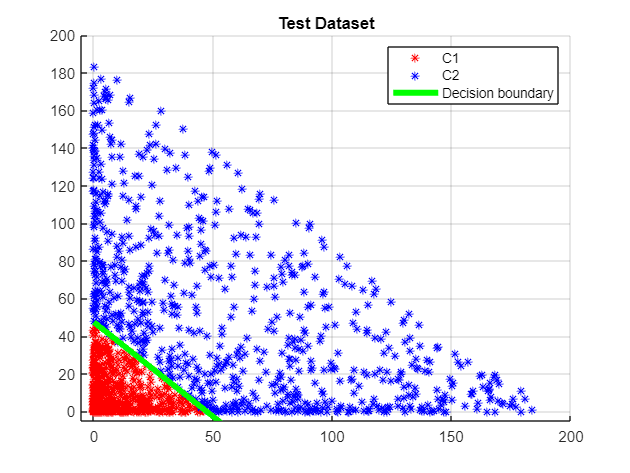

if Normalize_Data == false
    Vtest(:,1) = ((Utest(:,1)-Centre(1))) .* ((Utest(:,1)-Centre(1)));
    Vtest(:,2) = ((Utest(:,2)-Centre(2))) .* ((Utest(:,2)-Centre(2)));
elseif Normalize_Data == true
    Centre_test(1) = Centre(1);
    Centre_test(2) = Centre(2);
    Vtest(:,1) = ((Utest(:,1)-Centre_test(1))./(max(U_centered_train(:,1)))) .* ((Utest(:,1)-Centre_test(1))./(max(U_centered_train(:,1))));
    Vtest(:,2) = ((Utest(:,2)-Centre_test(2))./(max(U_centered_train(:,1)))) .* ((Utest(:,2)-Centre_test(2))./(max(U_centered_train(:,1))));
end

figure();
hold on 
grid on 
plot(Vtest(find(Ytest==1),1),Vtest(find(Ytest==1),2),'r*'); %C1
plot(Vtest(find(Ytest==2),1),Vtest(find(Ytest==2),2),'b*'); %C2
Xlim=xlim();
xspace = Xlim(1):0.1:Xlim(end);
BoundaryLine = (Theta_star(1) + xspace.*Theta_star(2))./(-Theta_star(3));
plot(xspace,BoundaryLine,'-g','LineWidth',4);
Ylim=ylim();
Ylim(1)=-5;
ylim(Ylim);
Xlim(1)=-5;
xlim(Xlim);
if Normalize_Data == true
    xlim([-0.1,1.1]);
    ylim([-0.1,1.1]);
end
hold off
title('Test Dataset');
legend({'C1','C2','Decision boundary'});

So the **classification error** over the *training set* is:

Phi_test = [ones(N_test,1) Vtest(:,1) Vtest(:,2)];
Y_test(find(Ytest==2),1) = 1;
Y_test(find(Ytest==1),1) = 0;

F_test = sigmoid(Phi_test*Theta_star);
Y_hat_test = round(F_test);

Er_test = (1/N_test) * sum(abs(Y_test-Y_hat_test));
fprintf('Error Rate on the test set = %2.2f %%',Er_test*100);

Error Rate on the test set = 0.20 %

## 5] **MATLAB mnrfit function:**

As we had done in the "ML_Ex1" matlab homework I wanto to compare the result obtained with the MATLAB mnrfit function.

Theta_matlab = -mnrfit(Vtrain,Ytrain);
Theta_matlab = Theta_matlab/max(Theta_matlab);
Phi = [ones(N_train,1) Vtrain(:,1) Vtrain(:,2)];

F_matlab = sigmoid(Phi*Theta_matlab);
Y_hat_train_matlab = round(F_matlab);

Er_train_matlab = (1/N_train) * sum(abs(Y-Y_hat_train_matlab));
fprintf(['Error Rate on the training set with MATLAB function = %2.10f %%\n' ...
    'Error Rate on the training set with above algorithm = %2.10f %%'],Er_train_matlab*100, Er_train*100);

Error Rate on the training set with MATLAB function = 0.1142857143 %
Error Rate on the training set with above algorithm = 0.1142857143 %

That is equal to the one we have obtained before.

The code performes like MatLab! :)